# Bifurcation diagram for a quantum graph on a periodic hexagonal grid

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

## Construct the quantum graph and find the first few eigenfunctions

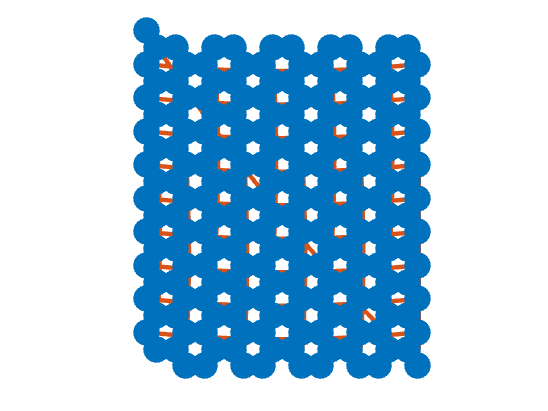

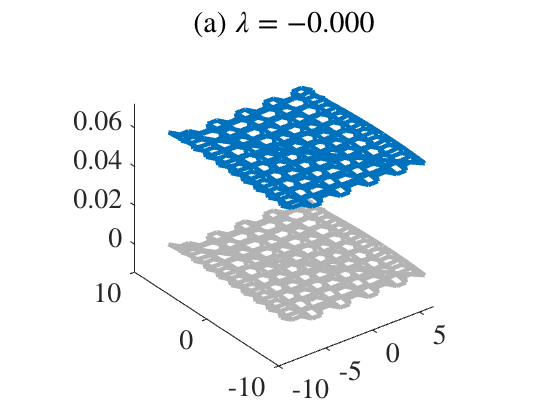

Saved to directory data/hex/012.
Run number is 12.


tag='hex';
[Phi,PhiX,extensionMap] =hexGridPeriodic(nx1=10,nx2=10,nx=20); % use the default values
nToPlot=1;
dataDir=eigenfunctionsSaveData(Phi,tag,nToPlot);

savePeriodicData(dataDir,PhiX,extensionMap)
Lambda0=-4;
options=continuerSet([],'LambdaThresh',-4.1,'NThresh',10,'plotFlag',false,'maxTheta',2);

#### Compute a large-amplitude edge-centered solution, save it to a file, and compute its continuation

x0=[0 0];
filenumber=saveHighFrequencyStandingWaveGraphical(dataDir,Lambda0,x0);

File saved to data/hex/012/savedFunction.001.
File number is 1. 


branch1=continueFromSaved(dataDir,filenumber,-4,options);

#### Compute a large-amplitude edge-centered solution, save it to a file, and compute its continuation

x0=[1/4, -sqrt(3)/4];
filenumber=saveHighFrequencyStandingWaveGraphical(dataDir,Lambda0,x0);
branch2=continueFromSaved(dataDir,filenumber,-4,options);

#### Compute a large-amplitude edge-centered solution, save it to a file, and compute its continuation

x0=[3/4 sqrt(3)/4];
filenumber=saveHighFrequencyStandingWaveGraphical(dataDir,Lambda0,x0);
options=continuerSet(options,'maxTheta',1.5,'NThresh',21.5,'minNormDelta',2e-3);ls
branch3=continueFromSaved(dataDir,filenumber,-4,options);

bifurcationDiagram(dataDir)

## Plot some solutions

plotSolution(dataDir,branch1,1)

plotSolution(dataDir,branch2,1)

plotSolution(dataDir,branch3,1)

plotSolution(dataDir,branch3,'last')